# Investigate data

Import data and organize it into the format expected by `trainNetwork`.

data = load("../data/fashionMNIST.mat");
yTrain = data.yTrain;
yTest = data.yTest;
xTrain = reshape(data.xTrain, 28, 28, 1, numel(yTrain));
xTest = reshape(data.xTest, 28, 28, 1, numel(yTest));

Get a random selection of 16 images from the test data and display the images and their labels.

The images are only 28-by-28, so increase the size to 84-by-84 so they are easier to see.

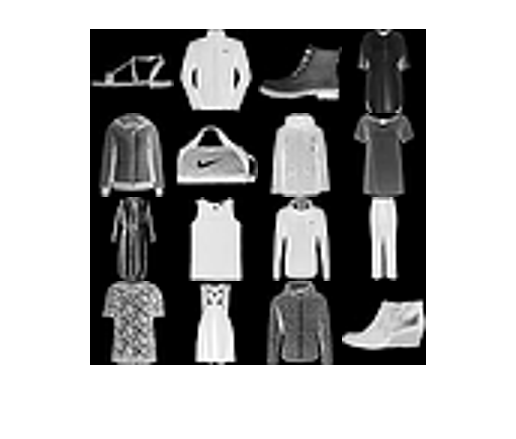

randidx = randperm(numel(yTest), 16);
randmontage = imtile(xTest(:, :, 1, randidx), "ThumbnailSize", [84 84]);
imshow(randmontage)

disp(yTest(randidx))

     Sandal 
     Coat 
     Ankle Boot 
     Dress 
     Coat 
     Bag 
     Coat 
     Shirt 
     Dress 
     T-Shirt 
     Pullover 
     Trouser 
     T-Shirt 
     Dress 
     Coat 
     Ankle Boot 



See the distribution of classes in the training and test data.

disp("Train data:")

Train data:


summary(yTrain)

     T-Shirt         6000 
     Trouser         6000 
     Pullover        6000 
     Dress           6000 
     Coat            6000 
     Sandal          6000 
     Shirt           6000 
     Sneaker         6000 
     Bag             6000 
     Ankle Boot      6000 


disp("Test data:")

Test data:


summary(yTest)

     T-Shirt         1000 
     Trouser         1000 
     Pullover        1000 
     Dress           1000 
     Coat            1000 
     Sandal          1000 
     Shirt           1000 
     Sneaker         1000 
     Bag             1000 
     Ankle Boot      1000 
